#### ADVANCED DIGITAL SIGNAL PROCESSING

NAME: **GIDEON OPOKU | **STUDENT ID:** 20735677 |** INDEX NUMBER:** PG3044620 |**

**LAB EXERCISE TWO: AM AND FM SINUSOIDAL SIGNAL**

**a.**

%Creating and Plotting the beat signal

$f\Delta$ = 32Hz

Tdur = 0.26 sec

$f_s$  = 11025 Hz

$f_c$ = 2000 Hz

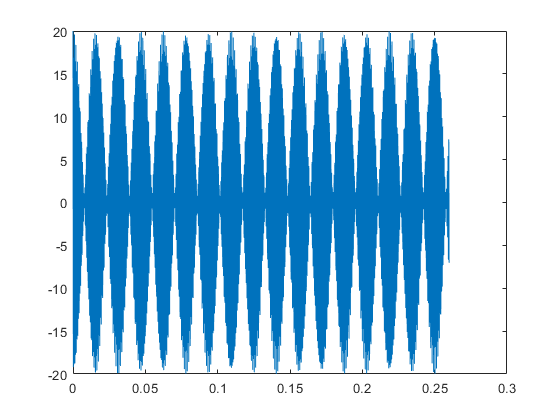

[xx,tt] = beat(10,10,2000,32,11025,0.26);
plot(tt,xx); 

**b.**

Using a window length of 2048

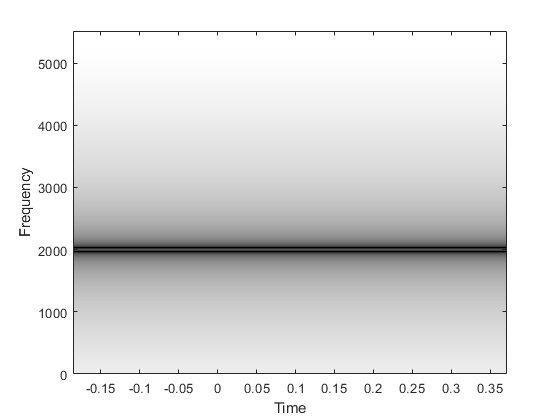

fsamp=11025;
specgram(xx,2048,fsamp); 
colormap(1-gray(256))

The correct frequency is present; 2032 Hz

**c.**

Using a window length of 16

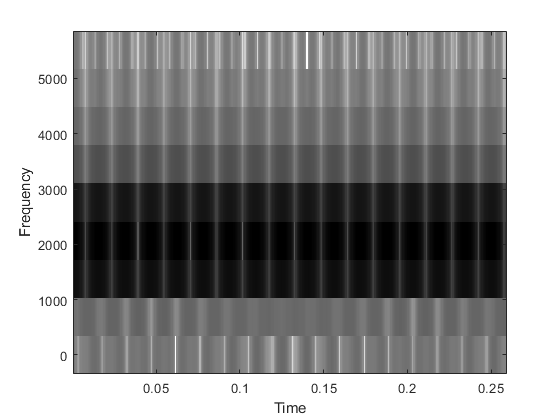

specgram(xx,16,fsamp); 
colormap(1-gray(256))

When the window size is small, the frequencies are not visibly clear and the spectrum appears rough and 

**4.3. Spectogram of a Chirp**

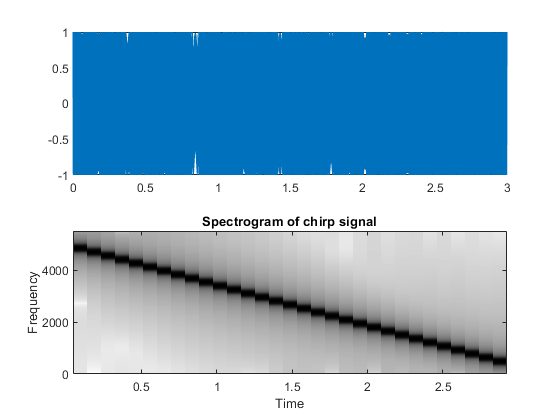

[xx,tt] = mychirp(5000,300,3,11025);
% listen to the signal
subplot(2,1,1)
% plots chirp
plot(tt,xx) 
subplot(2,1,2)
% spectrogram of the chirp signal
specgram(xx,2048,fsamp); 
colormap(1-gray(256)) 
title('Spectrogram of chirp signal'); 

The signal linearly chirps down

**4.4** A Chirp Puzzle

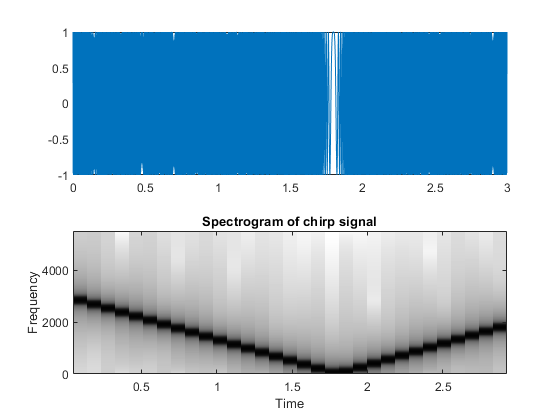

fsamp=11025; dur=3; f1=3000; f2=-2000;
[xx,tt] = mychirp(f1,f2,dur,fsamp);
subplot(2,1,1)
% plots chirp
plot(tt,xx) 
subplot(2,1,2)
specgram(xx,2048,fsamp); colormap(1-gray(256)) % spectrogram of the chirp signal
title('Spectrogram of chirp signal');

The signal linearly chirps down and up. 

** mychirp function**

function [xx,tt] = mychirp(f1,f2,dur,fsamp)
if(nargin<4), fsamp = 11025; end
tt = 0:1/fsamp:dur;
K = (f2-f1)/(2*dur);
xx = real(exp(1i*2*pi*(f1*tt+K*tt.*tt)));
soundsc(xx,fsamp); 
end
%{
MYCHIRP generate a linear-FM chirp signal
usage: xx = mychirp(f1,f2,dur,fsamp)
f1 = starting frequency
f2 = ending frequency
dur = total time duration
fsamp = sampling frquency (OPTIONAL: default is 11025)
xx = vector of sampls of the chirp signal
tt = vector
%}


**beat function**

%{
function [xx,tt] = beat(A,B,fc,delf,fsamp,dur)

BEAT compute samples of the sum of two cosine waves
usage:
[xx, tt] = beat(A, B, fc, delf, fsamp, dur)

A = amplitude of lower frequency cosine
B = amplitude of higher frequency cosine
fc = center frequency
delf = frequency difference
fsamp = sampling rate
dur = total time duration in seconds
xx = output vector of samples
Second Output:
tt = time vector corresponding to xx

%}
function [xx,tt]=beat(A,B,fc,delf,fsamp,dur)
if(nargin<4)
    fsamp=11025;
end
dt=1/fsamp;
tt=0:dt:dur;
psi1=2*pi*((fc-delf)*tt);
psi2=2*pi*((fc+delf)*tt);
xx=real(A*exp(1j*psi1)+B*exp(1j*psi2));
soundsc(xx,fsamp);

end